# Flow network

In this practical we''ll go over some basics of flow routing. By the end of this script, you'll be able to map surface water streams, delineating drainage basins and drainage divides. Calculating a flow network is one of the most important steps in topographic analysis! This is how you divide a landscape into streams and hillslopes on which (as we learned) different processes dominate.

clc
clear 
close all
DEM =  % load DEM

Now let's calculate the flow directions. You have a lot of options when creating a FLOWobj, e.g., multliple or single flow directions.  Often DEMs contain erroneous topographic depressions, which we need to account for before the flow can be properly routed. For this you can preprocess the DEM as shown below by carving or filling. If you have many lakes in the area, filling may be the better choice. If you're in mountainous terrain without lakes - go for 'carve'. We'll later in this course look at how these different options affect our results.

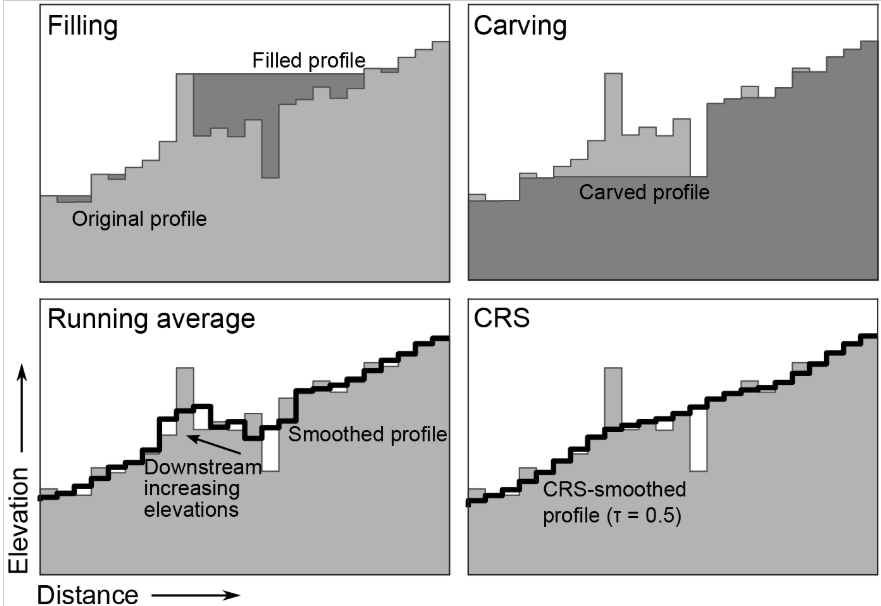f*rom Schwanghart and Scherler 2017*

As always when there's a new object, there's a whole zoo of methods you can use it with.

FD  = FLOWobj(DEM
methods FLOWobj

Let's calculate flow accumulation, which is the sum of all pixels (or area) that flows into each grid cell. 

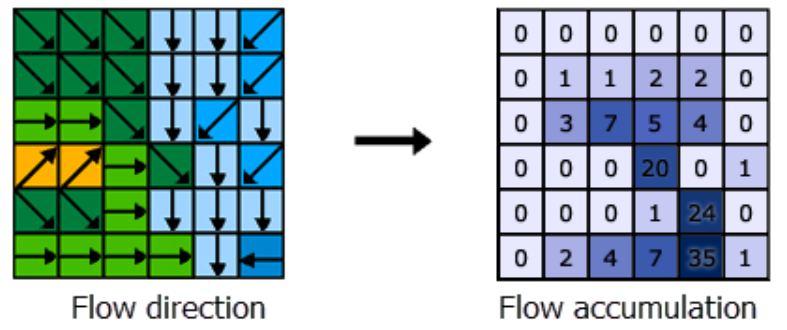

Here's a small cartoon to visualize how the flow direction (stored in FLOWobj) and flow accumulation look like on a grid (Source: ArcGIS).

Below, I use the log10 function in the plot command to make the color differences in the flow accumulation grid more pronounced. Zoom into image to really see the flow accumulationn visualized.

What unit is A in? Hint: open the variable in the variable explorer. Go to the .Z field in which the grid is stored and look.

A  = flowacc(FD);
set(gcf,'Units','normalized','Position',[0 0 1 1]); 
imageschs(DEM,log10(A)); % I'm just using the logarithm because accumulation values cover a range of many orders of magnitude

Now, let's calculate the drainage basins of the DEM. This can be done using the function 'drainagebasins'. The output is a raster with integer values representing different basins. You may want to shuffle the colors so that the drainage basins can be more easily distinguished in a plot ('shufflelabel'). As a small exercise, let's denote the area of each basin in the map. 

DB = drainagebasins(FD);
DB = shufflelabel(DB);
% plot the DEM with drainage basin overlay using 'imageschs'

Most of the area drains to the Rhine. The other major river is the Danube.

Time to delineate the stream network. This involves a new class, the STREAMobj. The STREAMobj needs some kind of information about what constitutes a stream. Usually, this is a drainage area threshold. A common approach is to use 1 km² = 1e6 m² as a critical drainage area above which a stream forms. Below is a slider for the minimum drainage area. Move the slider (then wait) and observe how the drainage network changes depending on the selected minimum area for stream initiation. Choose what appears to you like a reasonable value and move on.

MinArea = 7400000-20
S = STREAMobj(FD,'minarea',MinArea,'unit','map'); % delineate stream network

We can display our stream network with the plot command

imageschs(DEM,[],'colormap',landcolor)
hold on
plot(S,'b-')

What is happening in the southeastern corner of the DEM? Why are the streams linear and parallel there? Can you guess a reason?

Tip: Think back about the flow routing algorithms we applied in the beginning.

Solution discussed in lecture and/or in _key file.

There's a big river flowing out of Lake Constance to the south. This is incorrect. The Alpine Rhine flows north here into Lake Constance but DEM elevation errors paired with the carve algorithm, which needs to ensure water drains out at the edge of the DEM, make this weird error.

We can fix this by adding high elevation values at the southern end of the DEM, to make sure no river exits through the southern border of the DEM. Elevation values are stored in the Z-matrix of the DEM. The last row can be found with 'end'.

DEM.Z% index into last row of Z-matrix and make it 2000
% we need to update the FLOWobj and STREAMobj
FD  = ;
S = ; % delineate stream network

% plot DEM and stream network as above

Now the stream network is correct!

### Strahler order

Strahler order is a simple concept from mathematics used to characterize branchs of methematical trees. However, the concept has been widely adopted in hydrology to characterize rivers and their tribuatry networks.

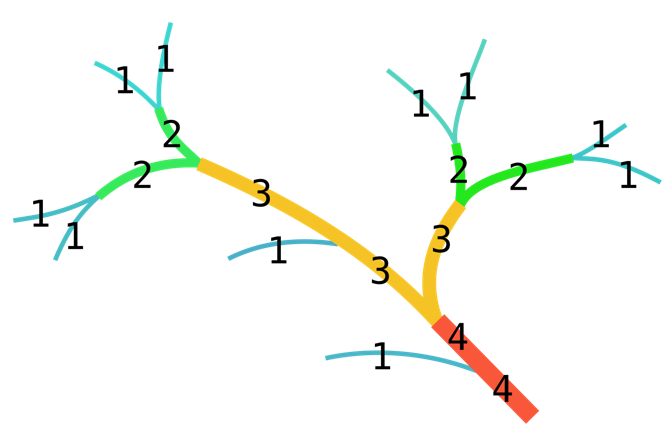*Wikipedia*

The uppermost tributaries are order 1 and when two 1's meet, an order 2 streams starts, etc.

Let's display our stream network in terms of strahler order with stream getting thicker with increasing order. Use the 'plotstreamorder' function:

figure()
% plot DEM
hold on
plotstreamorder(S,'colormap',[0, 0, 0.5],'LineWidth',[1 2 3 4 5 6 7]/3)    % plot stream accroding to Strahler order

Below is what common drainage patterns look like and they're reltationship with geology. Look at the drainage patterns you just generated. In which categories do they mostly fall and are there regional differences?

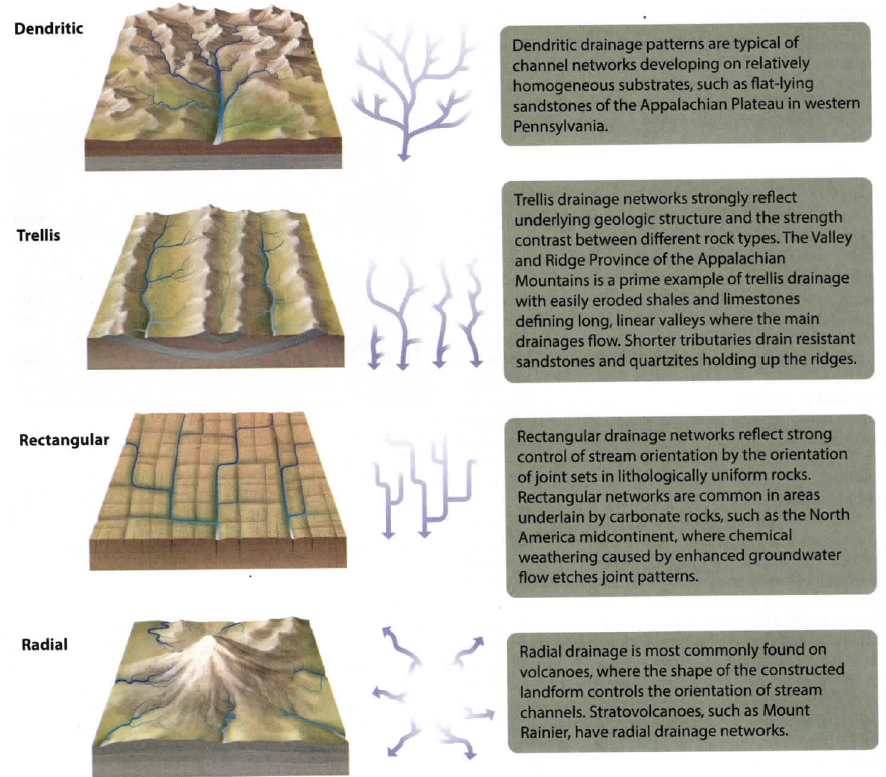

From Bierman & Montgomery 2020

### Drainage divides

We've delineated the flow of the streams. But we can also delineate the network of drainage divides. Analogous to the STREAMobj, which stores all the properties of a stream netowork, the DIVIDobj holds information about the network of drainage divides. You are experienced enough to figure out how to calculate a DIVIDEobj yourself. Choose 'topo' as a ordering type.  This orders divides by topographic prominance. 

This command will take a while to run, especially on an old computer (took ~5min for mine). Go and take a break or alternatively request the .mat file of the D variable from me.

D = 
D = % run 'divorder'command to add divide order to the DIVIDEobj. Use 'topo' option

Now, display the DEM toegther with the stream and divide network. You can plot divides the same way you plotted the streams.

figure()
set(gcf,'Units','normalized','Position',[0 0 1 1]); 
imageschs(DEM,[],'colormap',[1 1 1],'colorbar',false)  % plots DEM in white
hold on
% plot stream network in blue
plot(D,'limit',[2000 inf],'color','k') % good to use a lower limit for display to remove mini-divides

Is there anything you find surprising about the geometry of drainage divides in the study area? How do drainage divides and river patterns normally look like? What is different here?

Solution discussed in lecture and/or in _key file.